get paths, clear workspace

filePath = matlab.desktop.editor.getActiveFilename;
cd(filePath(1:strfind(filePath,'livescripts/custom_data_livescript')-1))
addpath(genpath(filePath(1:strfind(filePath,'livescripts/custom_data_livescript')-1)));
warning('off','MATLAB:dispatcher:UnresolvedFunctionHandle')
clear;close all;clc;

simulate 2D drift-diffusion data

w_sparse = W(W~=0);
sig = w_sparse(3); % diffusion coefficient 
d = 2; % spatial dimension
c = w_sparse(1:2)'; % drift velocity
N = 2^15; % number of particles 
numt = length(xs_obs{end}); % number of timepoints
dt = mean(diff(xs_obs{end})); % timestep
t = 0:dt:(numt-1)*dt; % timegrid
N0 = std(Xscell{1}(:,:,1)).*randn(N,d)+mean(Xscell{1}(:,:,1)); % initial conditions
Xscell = {N0+sqrt(2*dt*sig)*cumsum(randn(N,d,numt),3) + dt*c.*reshape((0:(numt-1)),1,1,numt)};
lhs = [1 0 0 1]; % specify lhs is d/dt mu
true_nz_weight_tags = {{'u^{1}_{t}',{'([x.^0.*y.^0.*t.^0]u^1)_{lap}','([x.^0.*y.^0.*t.^0]u^1)_{x}','([x.^0.*y.^0.*t.^0]u^1)_{y}'},[sig -c(1) -c(2)]}};
true_nz_weights = {[[1 1 0 0 -c(1)];[1 0 1 0 -c(2)];[1 2 0 0 sig];[1 0 2 0 sig]]};

Compute approximate particle distribution $U$ from particles *Xscell* 

exps = 1; %choose experiments from Xscell to use in regression (if Xscell contains multiple exps)
NN = N; %choose number of particles to use from each experiment
numx = 2^7 + 1; %choose histogram grid resolution
numsdv = inf;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0 1 1]];
scoord = 0;
Xsnz = [0 1]; %set extrinsic noise level

get_particle_distrib; %compute histogram

ET_load_data = 0.2330 


View histogram data

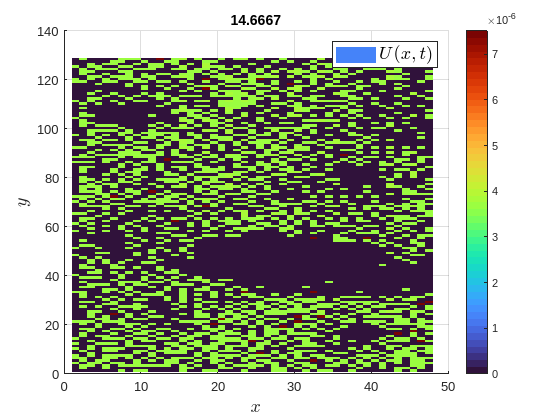

plotgap=10;
plot_distrib;

Choose model library

% local autonomous operators
max_dx = 0;
max_dt = 0;
polys = 0;
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {@(mat,lhs) find(all([mat(:,2)==0 mat(:,3)==0 ~ismember(mat,lhs,'rows')],2))};
toggle_comb = 1;

% local non-autonomous operators
driftpolys=[0:3]; drifttrigs=[];
diffpolys=[0:3]; difftrigs=[]; crossdrift=0;

% non-local operators
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[1:4],'Sing',[0],'Exp',[],'Singeps',[0.01],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 0.1360 


Set weak discretization

phi_class = {1,1};
sm_x = 3; % set ratio of query-point gap to test function radius in spatial dims
sm_t = 3; % set ratio of query-point gap to test function radius in time 

% manually set test function params
% p_x = 5; mxs = 31;
% tau_x = []; k_x = []; tauhat_x = []; 
% p_t = 3; mts = 16;
% tau_t = []; k_t = []; tauhat_t = [];

% set test function params using cornerpoint
tauhat_x = 4; tau_x = 10^-6;
p_x = []; mxs = 1;
tauhat_t = 4; tau_t = 10^-6;
p_t = []; mts = 1;

% rescale coordinates
scales = 2;

% use approx. variance for improved conditioning
covtol = 0;

% trim rows with low particle density
trim_tags = [1 zeros(1,dim-1) 0]; 
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-1;

set_discretization;

ET_setdisc = 0.6507 


View average FFT info

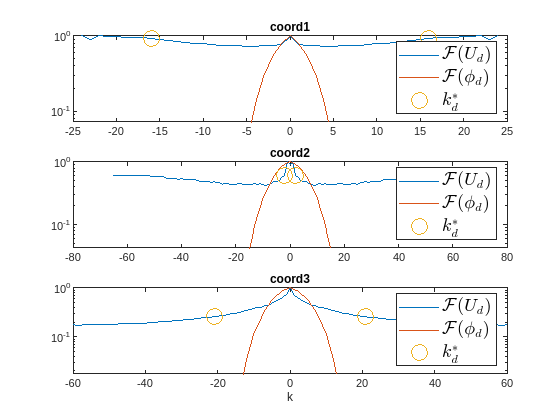

toggle_plot_fft = 1;
plot_Ufft;

Build linear systems

build_Gb;

ET_build_Gb = 3.0746 


MSTLSQP

lambda = 10.^(linspace(-4, 0, 100));
gamma_tol = Inf;
alpha = 1/(0.01*size(G,2)+1);
maxits = Inf;
sparsity_scale = 0;
excl_tags= {};
excl_tols = 0;
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 1.4117 


get_results

print_loc = 1;
get_results;


Recovered PDE: u^{1}_{t} = -3.96958e-06([x.^0.*y.^0.*t.^0]u^1)_{x} + 0.163015([x.^1.*y.^0.*t.^0]u^1)_{x} + -0.194786([x.^0.*y.^1.*t.^0]u^1)_{x} + -0.000207233([x.^1.*y.^1.*t.^0]u^1)_{x} + 0.000447109([x.^0.*y.^2.*t.^0]u^1)_{x} + -0.000266249([x.^2.*y.^0.*t.^0]u^1)_{x} + 8.71855e-08([x.^1.*y.^2.*t.^0]u^1)_{x} + 4.90899e-07([x.^2.*y.^1.*t.^0]u^1)_{x} + -2.72209e-07([x.^0.*y.^3.*t.^0]u^1)_{x} + -6.15893e-08([x.^3.*y.^0.*t.^0]u^1)_{x} + -3.85468e-05([x.^0.*y.^0.*t.^0]u^1)_{y} + -0.284305([x.^1.*y.^0.*t.^0]u^1)_{y} + 0.0301656([x.^0.*y.^1.*t.^0]u^1)_{y} + 6.65761e-05([x.^1.*y.^1.*t.^0]u^1)_{y} + 3.33011e-05([x.^0.*y.^2.*t.^0]u^1)_{y} + 0.00113787([x.^2.*y.^0.*t.^0]u^1)_{y} + -2.84794e-07([x.^1.*y.^2.*t.^0]u^1)_{y} + 6.44178e-07([x.^2.*y.^1.*t.^0]u^1)_{y} + -3.91512e-09([x.^0.*y.^3.*t.^0]u^1)_{y} + -1.82216e-06([x.^3.*y.^0.*t.^0]u^1)_{y} + 0.000298133([x.^0.*y.^0.*t.^0]u^1)_{lap} + 0.344326([x.^1.*y.^0.*t.^0]u^1)_{lap} + -0.0748845([x.^0.*y.^1.*t.^0]u^1)_{lap} + 0.00049771([x.^1.*y.^1.*t.^0

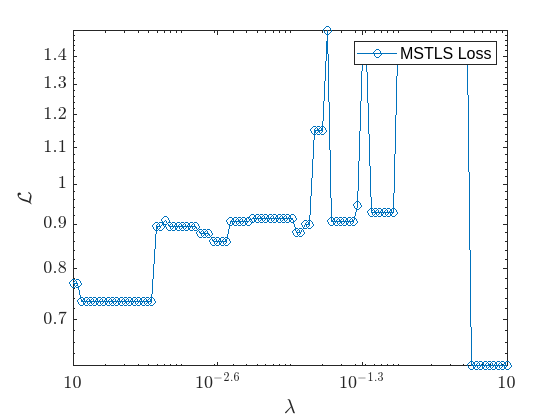

% Display loss
toggle_plot_loss = 1;
plot_loss;

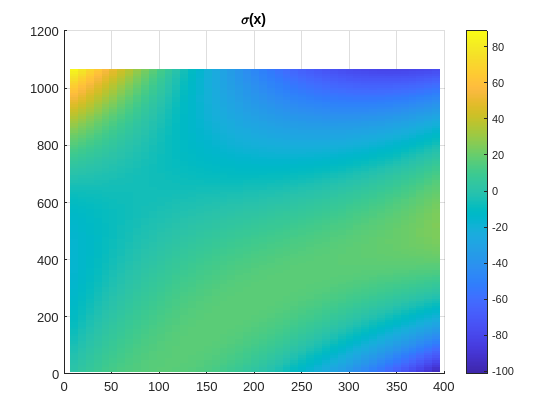

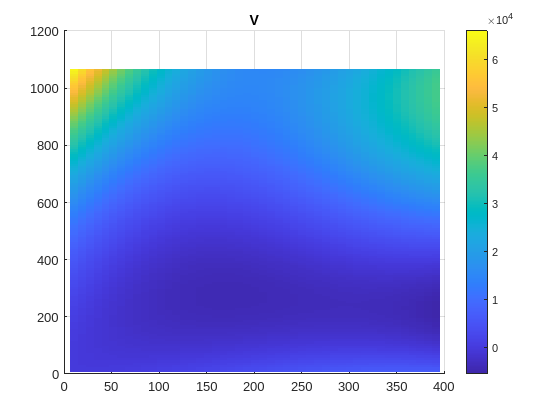

% Display drift/diffusion
toggle_plot_drift = 1;
plot_driftdiff;

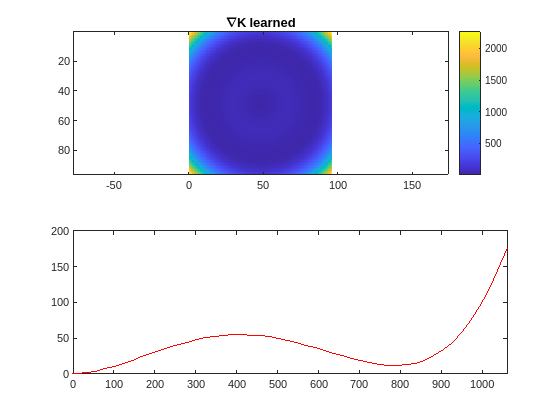


% Display interaction force
toggle_plot_IPforce = 1;
plot_K